# Final Project: PCA + SVM Portion

**Author:** Rex Rayburg

**Student ID:** 4336366

**D Value:** 66

This live-script will walk through the processing involved with performing PCA on an image classification dataset.

clear
clc
close all

## Part 1 - Data Processing

The dataset contains images of standard playing cards organized into labeled folders corresponding to each card type. Key characteristics of the dataset include:

- ~7,600 training images

- 265 validation images

- 265 testing images

- 53 total classes representing each unique playing card (including jokers)

- Images are 224 x 224 RGB color images

### Part A - Loading the Data

For now, I will be utilizing the random split that was already performed when the data was released to the public on Kaggle. This part will load the data into the workspace using datastores and then display a set of the training images for visualization.

% Define dataset path
dataPath = fullfile(pwd, 'input');

trainPath = fullfile(dataPath, 'train');
validPath = fullfile(dataPath, 'valid');
testPath  = fullfile(dataPath, 'test');

% Create imageDatastores
imdsTrain = imageDatastore(trainPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsValid = imageDatastore(validPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsTest = imageDatastore(testPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Basic dataset info
disp("Number of training images: " + numel(imdsTrain.Files));

Number of training images: 7624


disp("Number of classes: " + numel(categories(imdsTrain.Labels)));

Number of classes: 53


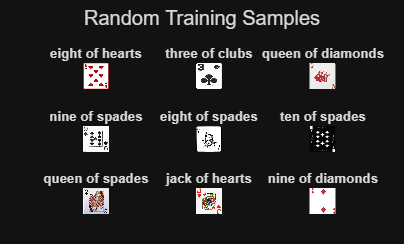


% Random sampling from training set
numSamples = 9;

randIdx = randperm(numel(imdsTrain.Files), numSamples);

figure;
for i = 1:numSamples
    img = readimage(imdsTrain, randIdx(i));
    
    subplot(3,3,i);
    imshow(img);
    
    title(string(imdsTrain.Labels(randIdx(i))), ...
        'Interpreter', 'none', ...
        'FontSize', 8);
end

sgtitle('Random Training Samples');

### Part B - Build and Visualize the Data Matrix T

This part will reshape the pixel matrices from the images into a large input matrix T, containing all the training data. The process can be described by the following steps:

- Slice original image into columns vectors of pixels

- Vertically concatenate each column with the next

- Repeat 1 & 2 for each training image

- Horizontally concatenate the reshaped image vectors (50176,1) into a (50176,N_samples) matrix.

% Define image size
imgSize = [224 224];

numImages = numel(imdsTrain.Files);
numPixels = prod(imgSize);

% Preallocate data matrix
T = zeros(numPixels, numImages);

% Build matrix T
for i = 1:numImages
    
    img = readimage(imdsTrain, i);
    
    % Convert to grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize to consistent dimensions
    img = imresize(img, imgSize);
    
    % Convert to double for PCA
    img = im2double(img);
    
    % Flatten (column-wise stacking)
    vec = img(:);
    
    % Store as column
    T(:, i) = vec;
end

disp("Data matrix size:");

Data matrix size:


disp(size(T));   % [50176, N]

       50176        7624



**Visualize the Data Matrix T**

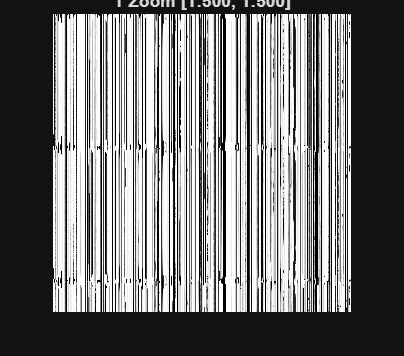

% Define region of interest
rowStart = 1;
rowEnd   = 500;

colStart = 1;
colEnd   = 500;

T_zoom = T(rowStart:rowEnd, colStart:colEnd);

figure;
imshow(T_zoom, []);
title(sprintf('T Zoom [%d:%d, %d:%d]', rowStart, rowEnd, colStart, colEnd));

**Analysis:** There isn't much going on in here. Most pixels are white, which makes sense given the common visual structure of playing cards. There are black streaks that represent the graphics on the cards, including the suit symbol, value, and artwork on the card.

### Part C - Mean Face

This section will compute the mean face of the card images

% Compute the mean across the rows 
m = mean(T, 2);

m =     0.7490
    0.7545
    0.7580
    0.7594
    0.7593
    0.7586
    0.7592
    0.7576
    0.7576
    0.7578
    0.7584
    0.7579
    0.7582
    0.7596
    0.7608


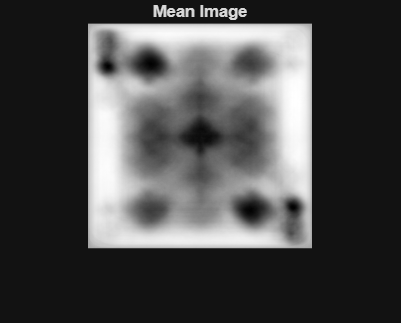


imgSize = [224 224];

meanImg = reshape(m, imgSize);

figure;
imshow(meanImg, []);
title('Mean Image');

The mean image looks similar to a real playing card, with a color emphasis in regions of shared attributes across the various cards. This includes the card identifier in the top left and bottom right, as well as the arrangement of the suit symbols across the center area of the card.

### Part D - PCA Analysis

This section will implement PCA from scratch to avoid the pca() functions overhead. Unfortunately, passing the raw pixel intensities presented memory errors in the system, prompting this approach instead.

% Center the data with the mean
A = T - m;

% Calculate the reduced covariance matrix
C = A' * A;

% Compute the eigenvalues
[U, S] = eig(C);

% Sort eigenvalues descending
[eigenvals, idx] = sort(diag(S), 'descend');
U = U(:, idx);

% Calculate the explained variance
explained = eigenvals / sum(eigenvals) * 100;
cumVar = cumsum(explained);

k = find(cumVar >= 95, 1);

fprintf('Components for 95%% variance: %d\n', k);

Components for 95% variance: 1443


The following code block will plot the percent variance explained vs. the eigenvectors. It will also highlight the calculated point for 95% variance, which we will use moving forward for our model.

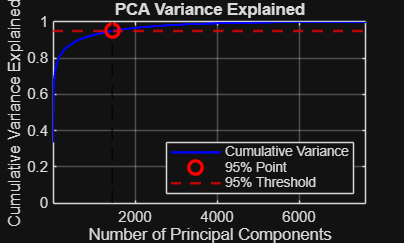

% Convert to 0–1 scale
cumVarNorm = cumVar / 100;

% X-axis: component index
x = 1:length(cumVarNorm);

figure;
plot(x, cumVarNorm, 'b', 'LineWidth', 1.5);
hold on;

% Highlight 95% point
plot(k, cumVarNorm(k), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% Horizontal dotted line at 95%
yline(0.95, 'r--', 'LineWidth', 1.5);

% Vertical line at k
xline(k, 'k--', 'LineWidth', 1);

% Labels
xlabel('Number of Principal Components');
ylabel('Cumulative Variance Explained');
title('PCA Variance Explained');

% Axis limits
ylim([0 1]);
xlim([1 length(cumVarNorm)]);

grid on;
legend('Cumulative Variance', '95% Point', '95% Threshold', 'Location', 'southeast');

**Analysis:** The plot shows that the percent variance described by the eigenvectors increases exponentially for the first 1000 or so eigenvectors, before saturating near 2000 eigenvectors. 95% seems to be on the latter end of the exponential decay, so for computational effort, it may have been better to use a 90% variance threshold.

The following block of code will plot the top 9 eigenvectors as reshaped images to visualize the features of the data they represent.

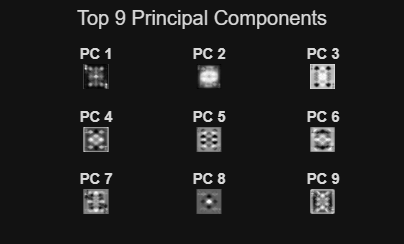

% Compute the pixel space eigenvectors
V = A * U;   % size: 50176 x 7624

% Normalize eigenvectors
for i = 1:size(V,2)
    V(:,i) = V(:,i) / norm(V(:,i));
end

% Extract the top 9 eigenvectors
V_top = V(:, 1:9);

% Reshape and display these eigenvectors
imgSize = [224 224];

figure;

for i = 1:9
    eigImg = reshape(V_top(:,i), imgSize);
    
    subplot(3,3,i);
    imshow(eigImg, []);
    title(sprintf('PC %d', i));
end

sgtitle('Top 9 Principal Components');

**Analysis:** These top principal components show the dominant patterns of variation across the dataset, not actual cards. The first few eigenvectors capture large-scale, consistent structure, most notably the card outline (bright/dark borders) and global symmetry, which is expected since all cards share the same rectangular shape and centered layout. You can also see recurring emphasis in the corner regions, where rank and suit symbols typically appear, indicating that these areas contribute strongly to variance. Later components begin to highlight more localized patterns, such as clusters resembling suit positions or central symbols, though they appear blurred because PCA averages variation rather than isolating discrete features. Overall, these eigenvectors tell us that the dataset's variance is dominated by 

## Part 2 - Feature Extraction

This part will project the training and testing images into the K-dimensional eigenvector space to obtain compact feature vectors.

### Part A - Project Training Images

numTrain = numel(imdsTrain.Files);
V_k = V(:, 1:k);

V_k =    -0.0032   -0.0056    0.0035    0.0101   -0.0046   -0.0054    0.0027   -0.0014   -0.0086    0.0074   -0.0018   -0.0015   -0.0055   -0.0016   -0.0016   -0.0050    0.0032    0.0086    0.0015   -0.0008   -0.0003    0.0002   -0.0051   -0.0037    0.0042   -0.0028    0.0020   -0.0014    0.0003    0.0026    0.0041    0.0039   -0.0037    0.0072    0.0000   -0.0003   -0.0022    0.0022   -0.0010   -0.0009   -0.0021    0.0002   -0.0004    0.0005    0.0031    0.0023   -0.0060    0.0009   -0.0043    0.0001
   -0.0034   -0.0057    0.0035    0.0103   -0.0048   -0.0057    0.0026   -0.0016   -0.0087    0.0074   -0.0020   -0.0013   -0.0058   -0.0017   -0.0025   -0.0048    0.0026    0.0090    0.0013   -0.0006   -0.0005    0.0002   -0.0057   -0.0034    0.0036   -0.0022    0.0016   -0.0015    0.0008    0.0023    0.0049    0.0035   -0.0031    0.0067   -0.0003    0.0002   -0.0026    0.0021   -0.0016   -0.0006   -0.0023    0.0010   -0.0005    0.0006    0.0023    0.0021   -0.0059    0.0009   -0.0043   

K = size(V_k, 2);

% Initialize feature + label matrices
W_train = zeros(K, numTrain);
y_train = zeros(numTrain, 1);

for i = 1:numTrain
    
    % Read image
    img = readimage(imdsTrain, i);
    
    % Grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize
    img = imresize(img, imgSize);
    
    % Convert
    img = im2double(img);
    
    % Vectorize
    vec = img(:);
    
    % Center using training mean
    vec_centered = vec - m;
    
    % Project into PCA space
    w = V_k' * vec_centered;
    
    % Store feature vector
    W_train(:, i) = w;
    
    % Extract label (from folder name)
    y_train(i) = double(imdsTrain.Labels(i));
end

% Display sizes
fprintf('W_train size: %d x %d\n', size(W_train,1), size(W_train,2));

W_train size: 1443 x 7624


fprintf('y_train size: %d x %d\n', size(y_train,1), size(y_train,2));

y_train size: 7624 x 1


### Part B - Project Testing Images

numTest = numel(imdsTest.Files);
K = size(V_k, 2);

% Initialize feature + label matrices
W_test = zeros(K, numTest);
y_test = zeros(numTest, 1);

for i = 1:numTest
    
    % Read image
    img = readimage(imdsTest, i);
    
    % Grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize
    img = imresize(img, imgSize);
    
    % Convert
    img = im2double(img);
    
    % Vectorize
    vec = img(:);
    
    % Center using training mean
    vec_centered = vec - m;
    
    % Project into PCA space
    w = V_k' * vec_centered;
    
    % Store feature vector
    W_test(:, i) = w;
    
    % Extract label
    y_test(i) = double(imdsTest.Labels(i));
end

% Display sizes
fprintf('W_test size: %d x %d\n', size(W_test,1), size(W_test,2));

W_test size: 1443 x 265


fprintf('y_test size: %d x %d\n', size(y_test,1), size(y_test,2));

y_test size: 265 x 1


## Part 3 - Card Recognition

This section will train and evaluate classifiers using the previously computed PCA features

### Part A - KNN Classifier

This section will train a KNN classifier on W_train and y_train.

% Ensure correct orientation: samples x features
X_train = W_train';
X_test  = W_test';

% K values to test
K_values = [1, 3, 5, 7];

accuracies = zeros(length(K_values), 1);

for i = 1:length(K_values)
    
    K = K_values(i);
    
    % Train KNN model
    mdl = fitcknn(X_train, y_train, ...
        'NumNeighbors', K, ...
        'Standardize', true);
    
    % Predict on test data
    y_pred = predict(mdl, X_test);
    
    % Compute accuracy
    acc = sum(y_pred == y_test) / length(y_test) * 100;
    
    accuracies(i) = acc;
end

%% Display results in table

resultsTable = table(K_values', accuracies, ...
    'VariableNames', {'K', 'Accuracy_percent'});

disp(resultsTable);

    K    Accuracy_percent
    _    ________________

    1         19.623     
    3         13.962     
    5         7.1698     
    7         7.1698     



**Analysis:** Peak observed accuracy is 19.623%. This is very low, but not unexpected for this dataset. With 53 classes, random guessing would yield an accuracy 1.9%. Our result for the KNN classifier shows a 10x performance increase compared to the random guessing case. Regardless though, the generally low accuracy indicates that the PCA isn't able to translate the raw pixel intensities into discriminative features for analysis. PCA captures directions of maximum variance, which may not correlate to areas tied to class separation. For example, what actually varies in the images are lighting, background shading, and rotations. Meanwhile, what really matters for classification are things like the suit symbols, rank text, and corner details. Therefore, additional preprocessing must be done to convert the raw pixel intensities into a more meaningful feature before applying PCA. The next step is to try using edge detection methods on the raw images before PCA and observing the difference in performance. I will also run both setups on additional SVM models.